L1=0.5; %side length
M=2000; %number of samples
dx1=L1/M; %src sample interval
x1=-L1/2:dx1:L1/2-dx1; %src coords
y1=x1;
lambda=0.5*10^-6; %wavelength

z=1; %propagation dist (m)

%parameters for HG00 input signals
w_in = 1e-2;        %width of HG00 signal
x1c = 1.5e-2;         %x-axis position of center of first HG00 signal
y1c = 0;            %y-axis position of center of first HG00 signal
x2c = -1.5e-2;        %x-axis position of center of second HG00 signal
y2c = 0;            %y-axis position of center of second HG00 signal


%generate two HG00 input signals

[X1,Y1]=meshgrid(x1,y1);
u1 =  exp(-((X1-x1c).^2 + (Y1-y1c).^2)/(w_in^2)); %first HG00 signal
u2 =  exp(-((X1-x2c).^2 + (Y1-y2c).^2)/(w_in^2)); %second HG00 signal

uin = u1 + u2;
I1=abs(uin.^2); %src irradiance


%Plot input signal 

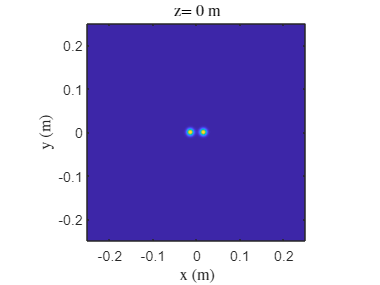

figure(1)
imagesc(x1,y1,I1);
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title('z= 0 m')

uout=propTF(uin,L1,lambda,z); %propagation
%u2=propIR(u1,L1,lambda,z); %propagation
x2=x1; %obs coords
y2=y1;
I2=abs(uout.^2); %obs irrad


%Plot output signal

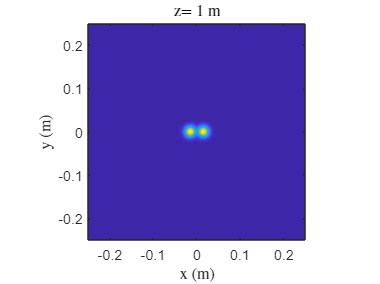

figure(2) %display obs irrad
imagesc(x2,y2,nthroot(I2,3));%stretch image contrast
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title(['z= ',num2str(z),' m']);